# Prepare the French dataset

% clear the environment 
clear all 
close all 
clc 

% read the data from file 
data = read_dataset_file("new_dataset.csv");

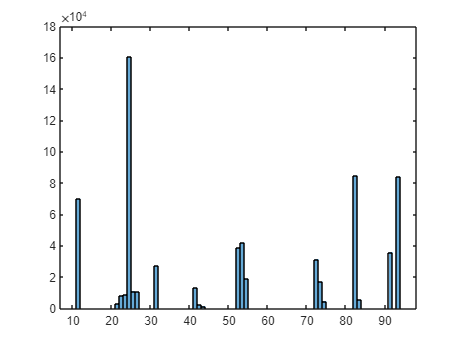

% Province 
province_data = data(:, 12);
histogram(province_data)

% p = draw_pie(province_data)

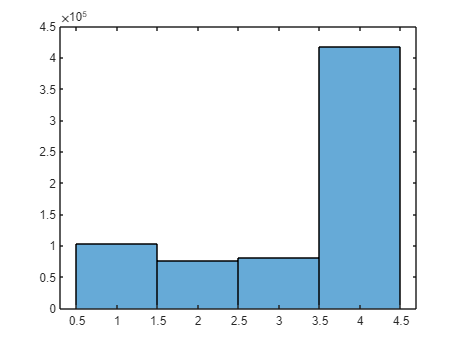

% set the group data 
density_data = data(:, 11);

density_group_1 = find(density_data < 50);
density_group_2 = find(density_data >= 50 & density_data < 100);
density_group_3 = find(density_data >= 100 & density_data < 200);
density_group_4 = find(density_data >= 200);

density_data(density_group_1) = 1;
density_data(density_group_2) = 2;
density_data(density_group_3) = 3;
density_data(density_group_4) = 4;

histogram(density_data)

% p = draw_pie(density_data)

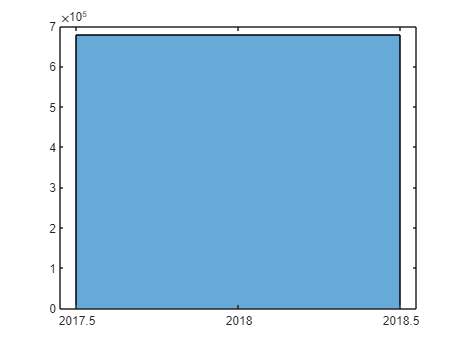

% issue date year 
issue_date = data(:, 1);
issue_date(data(:,1)>=0) = 2018;

histogram(issue_date)

% p = draw_pie(issue_date)

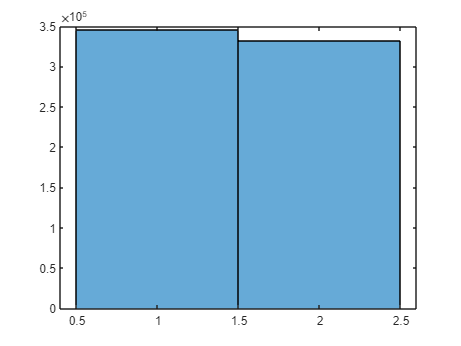

% car type 
car_type = data(:, 10);
histogram(car_type)


% p = draw_pie(car_type)

% car usage 
car_usage = data(:, 9);

k = hist(car_usage, unique(car_usage))

k =       162736      159861       53394       25179       34753       28548       17707       13585      166024       12178        4047


p = k./length(car_usage)*100

p =    24.0019   23.5779    7.8751    3.7137    5.1257    4.2105    2.6116    2.0037   24.4869    1.7961    0.5969



% merge the groups with less than 0.5% samples 
removeSmallUsageGroups = 0.5;
index = find( p < removeSmallUsageGroups);

for i = 1 : length(index)
    car_usage(find(car_usage == index(i))) = 72;
end 

unique_categories = unique(car_usage)

unique_categories =      1
     2
     3
     4
     5
     6
    10
    11
    12
    13


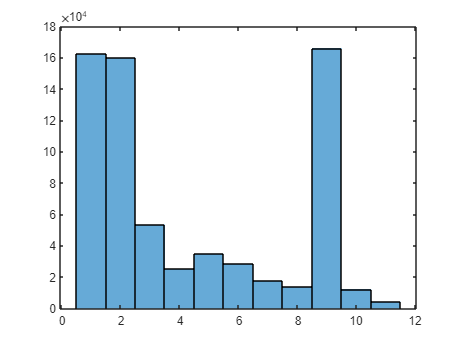


for i = 1 : length(unique_categories)
    car_usage(find(car_usage == unique_categories(i))) = 100+i;
end 

car_usage = car_usage - 100;

histogram(car_usage)

% p = draw_pie(car_usage)

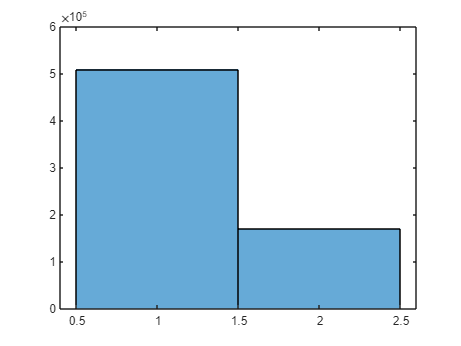

% duration of policy 
duration_policy = data(:, 3);
duration_policy(find(duration_policy >= 1)) = 2; 
duration_policy(find(duration_policy < 1)) = 1; 

histogram(duration_policy)


% p = draw_pie(duration_policy)

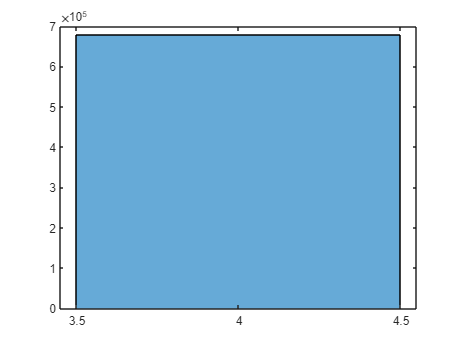

% number of passengers 
passengers = data(:, 3);
passengers(find(passengers >= 0)) = 4;

histogram(passengers)

% p = draw_pie(passengers)

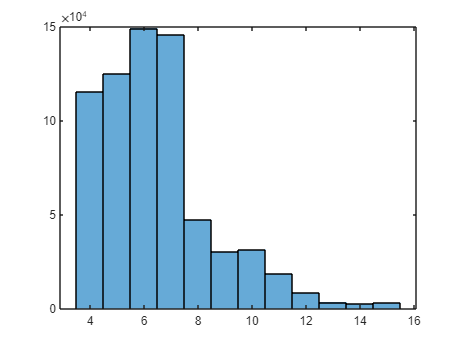

% number of cylindar 
cylinders = data(:, 5);

histogram(cylinders)

% p = draw_pie(cylinders)

% Car Price 
car_price = data(:, 14)*350000;
eco_class = find(car_price <= 5000000000)

eco_class =     13
    17
    28
    34
    47
    52
    72
    74
    81
    86


mid_calss = find(car_price > 5000000000 & car_price <= 10000000000)

mid_calss =      1
     3
     4
     8
     9
    12
    18
    19
    21
    22


lux_class = find(car_price > 10000000000)

lux_class =      2
     5
     6
     7
    10
    11
    14
    15
    16
    20


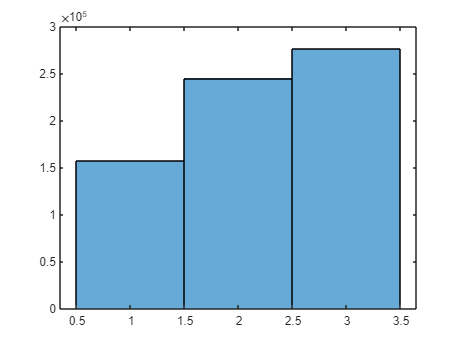


car_price(eco_class) = 1;
car_price(mid_calss) = 2;
car_price(lux_class) = 3; 

histogram(car_price)

% p = draw_pie(car_price)

% insurance price 
insurance_price = data(:, 15); 
insurance_price (find(insurance_price >= 0)) = 1000;

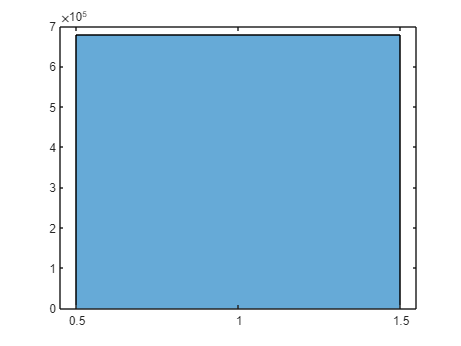

% other coverages 
other_coverage = data(:, 16);
other_coverage(find(other_coverage > 0)) = 1;
other_coverage(find(other_coverage == 0)) = 1;

histogram(other_coverage)

% p = draw_pie(other_coverage)

% customer type -- age
customer_type = data(:, 7)

customer_type =     52
    65
    53
    53
    52
    52
    52
    67
    52
    42


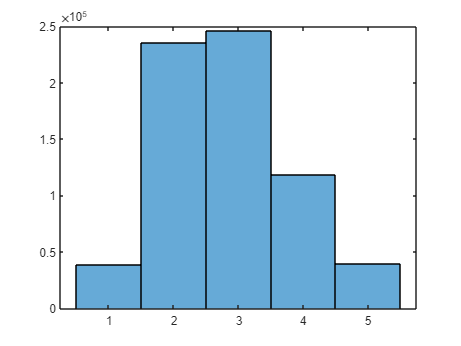


customer_type (find(customer_type  <= 25)) = 1;
customer_type (find(customer_type  > 25 & customer_type <= 40))   = 2;
customer_type (find(customer_type  > 40 &  customer_type <= 55))  = 3;
customer_type (find(customer_type  > 55 & customer_type  <= 70)) = 4;
customer_type (find(customer_type  > 70 ))                 = 5;

histogram(customer_type)


% p = draw_pie(customer_type)

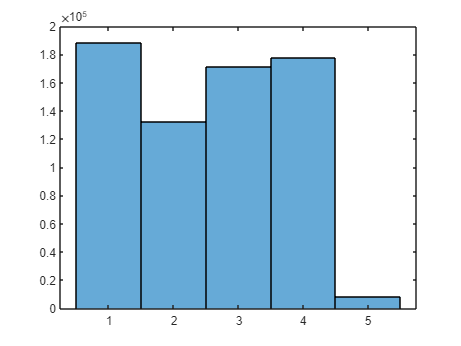

% car age 
car_age = data(:, 6);

car_age(find(car_age <= 2)) = 1;
car_age(find(car_age > 2 & car_age <= 5))   = 2;
car_age(find(car_age > 5 & car_age <= 10))  = 3;
car_age(find(car_age > 10 & car_age <= 20)) = 4;
car_age(find(car_age > 20))                 = 5;

histogram(car_age)


% draw_pie(car_age)

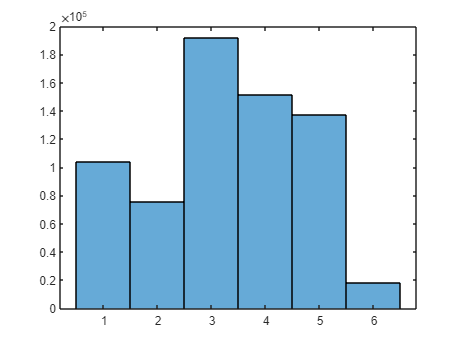

% car color -- area 
car_color = data(:, 4);
histogram(car_color)

% p = draw_pie(car_color)

% discounts -- molusbonus
discounts = data(:, 8);
discounts(find(discounts <  100)) = 1

discounts =      1
     1
     1
     1
     1
     1
     1
     1
     1
     1


discounts(find(discounts >= 100)) = 2 

discounts =      1
     1
     1
     1
     1
     1
     1
     1
     1
     1


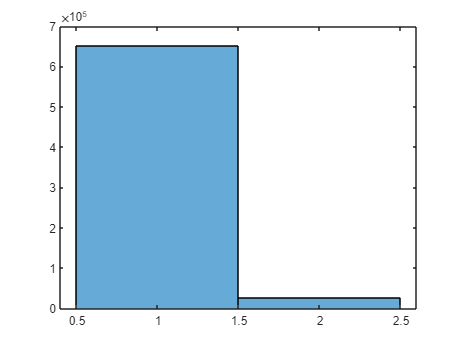

histogram(discounts)


histogram(discounts)

% p = draw_pie(discounts)

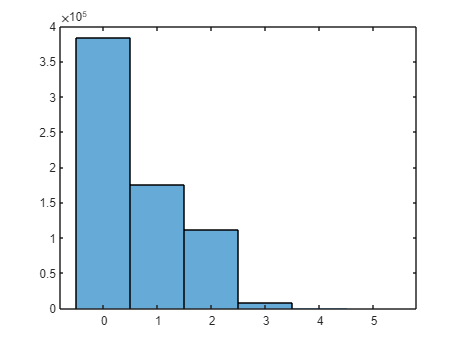

% Non Cliam Data
NCD = data(:, 8);

NCD(find(NCD <= 50)) = 0;
NCD(find(NCD >  50  &   NCD <= 75)) = 1;
NCD(find(NCD >  75  &   NCD <= 100)) = 2;
NCD(find(NCD >  100  &   NCD <= 150)) = 3;
NCD(find(NCD >  150  &   NCD <= 200)) = 4;
NCD(find(NCD >  200)) = 5;

histogram(NCD)


% p = draw_pie(NCD)

% Settlement_delay_days
settlement_days = data(:, 15)

settlement_days =     89
    41
   269
    48
   137
   213
   111
    54
     3
    84


settlement_days = settlement_days (find(settlement_days ~= 0));
mean(settlement_days)

ans = 61.2365

std(settlement_days)

ans = 60.7327

max(settlement_days)

ans = 614

min(settlement_days)

ans = 1

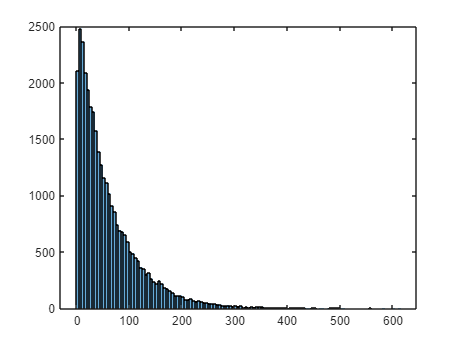

histogram(settlement_days)

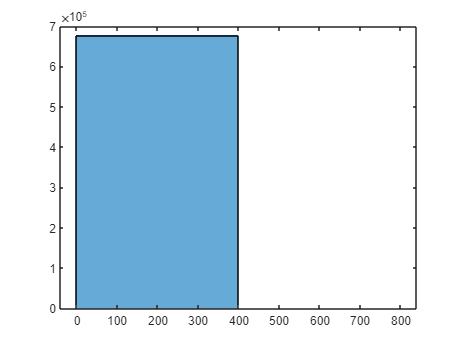

% reporting delay days
reporting_delay = data(:, 15);
% reporting_delay = reporting_delay(find(reporting_delay ~= 0));
histogram(reporting_delay,2)

% make the final dataset 
french_data_set = [province_data, density_data, issue_date, car_type, car_usage, ...
                duration_policy, passengers, cylinders, car_price, insurance_price, ...
                other_coverage, customer_type, car_age, car_color, discounts, ...
                NCD];
csvwrite("normalized_french_features.csv", french_data_set);

## Generate and write labels to the file

% has the customer claim? 
has_claim = data(:, 2); 
has_claim(find(has_claim > 0)) = 1; 

% how much we should pay to the policyholder 
claim_amount = data(:, 13)

claim_amount =         3000
        4000
        8000
        4000
        2000
       10000
        2000
        4000
       11000
        9000


% payment month after its occurance 
payment_month = data(:, 15);

% write the targets to the file 
french_labels = [has_claim, payment_month, claim_amount]

french_labels =            1          89        3000
           1          41        4000
           1         269        8000
           1          48        4000
           1         137        2000
           1         213       10000
           1         111        2000
           1          54        4000
           1           3       11000
           1          84        9000


csvwrite("french_features_LABELs.csv", french_labels );
